# Linux® Container

This example shows how to create and run a bash command in an Ubuntu® Linux® container using the **Interface for Desktop Docker Client** toolbox.

## Pull Linux Image

Create the image using the following code in the MATLAB command line. This docker image, `ubuntu:latest`, is pulled from Docker Hub repository.

docker.pull("ubuntu:latest")

latest: Pulling from library/ubuntu
Digest: sha256:703218c0465075f4425e58fac086e09e1de5c340b12976ab9eb8ad26615c3715
Status: Image is up to date for ubuntu:latest
docker.io/library/ubuntu:latest



If you open the Docker desktop application, you can see the Ubuntu image listed.

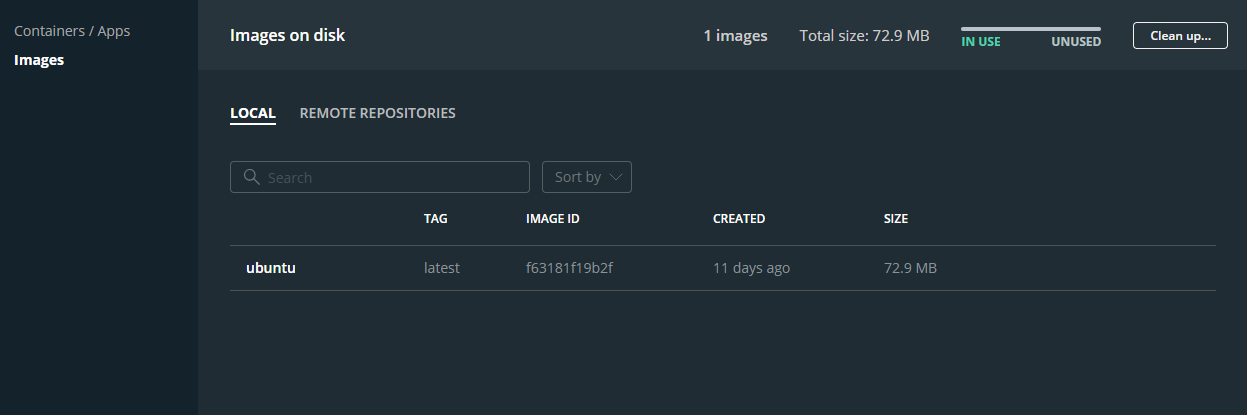

## Create and Launch A Container

With the image available on your system, you can now create and launch a container that can run a bash command, such as `echo`. To create the container, use the `docker.create` function in the MATLAB command line. The `COMMAND` and `ARG` arguments result in the bash command `echo "Hello MATLAB!"` to be executed when the container runs.

docker.create("ubuntu:latest","echo","Hello MATLAB!","name","my_bash_terminal");

5f527e8a72ee332aa5671096c406e30eeb38b1d40ea3435ae19d04d114f7ec03



If you open the Docker Desktop application, you can see your container has been created.

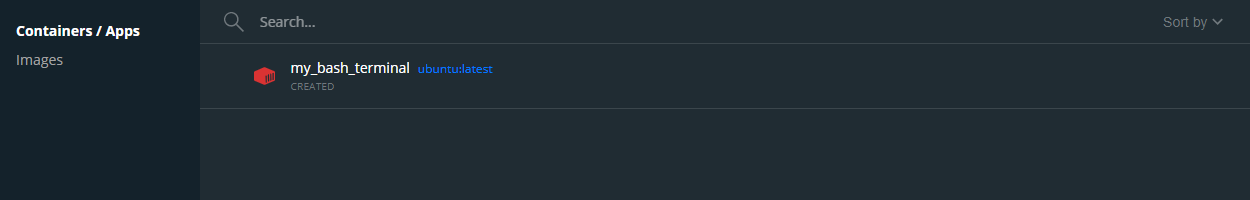

You can now run the container using the `docker.start` function. The `attach` option allows the standard output of the container to be sent to the output of the function; otherwise the function output will be the name of the container.

docker.start("my_bash_terminal","attach",true)

ans =     "Hello MATLAB!
     "


## Cleanup Container and Image

When you are done, you can remove the container using the `docker.rm` function.

docker.rm("my_bash_terminal","force",true);

You can also remove the image using the `docker.rmi` function, however Docker images can and should be reused allowing fast container creation.

docker.rmi("ubuntu:latest");

*Copyright 2021 The MathWorks, Inc.*